clc; clear all; close all;

%simulation settings (timespan, initial population sizes, parameter values)
t0 = 0;                 	% start time of simulation [in months]
tfinal = 200;               % end time of simulation [in months]
y0 = [2  3  4]              % initial state i.e. number of plants, hares, and lynx at t=0

y0 =      2     3     4


tspan = [t0 tfinal];        % time span defined by the start and end times of the simulation [in months]
a1 = 5                      % predation success rate parameter ("how likely that the plant dies if it meets a hare")

a1 = 5

a2 = 0.7                    % predation success rate parameter ("how likely that the hare dies if it meets a lynx")

a2 = 0.7000

b1 = 2 % hare population increase rate due to predation on plants ("how much food a hare gets out of eating a plants")

b1 = 2

b2 = 3 % lynx population increase rate due to predation on hare ("how much food a lynx gets out of eating a hare")

b2 = 3

d1 = 0.7 % per capita death rate of the Hare

d1 = 0.7000

d2 = 0.06 % per capita death rate of the Lynx

d2 = 0.0600

sjsdjdisdj hello 

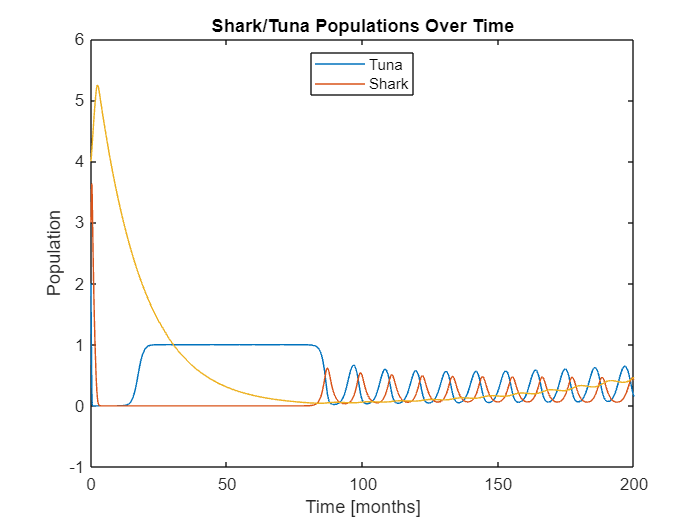

%simulate model
% The system of ordindary differential equations for sharks and tuna are
% solved numerically by taking tiny steps forward in time and estimating
% the solution.
[t,y] = ode23(@(t,y) plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

%plot population size in time
% next we plot our results and label the axes
% plotting the population over time
figure("Name",'Shark-Tuna')
plot(t,y)
title('Shark/Tuna Populations Over Time')
xlabel('Time [months]')
ylabel('Population')
legend('Tuna','Shark','Location','North')

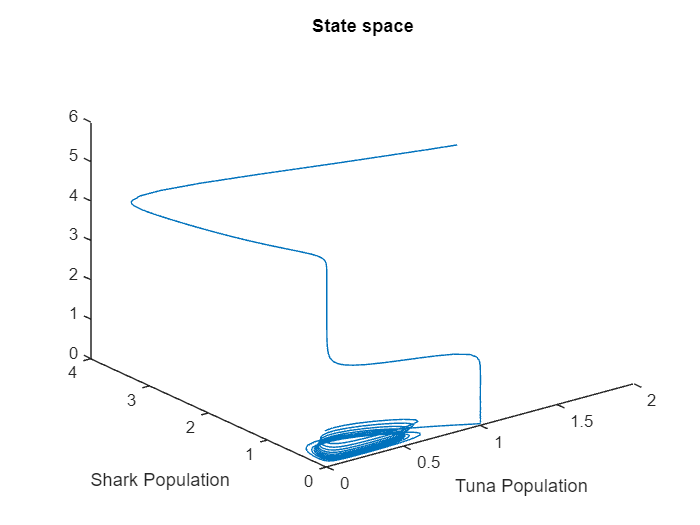


%plot state space
% Now, we are also going to plot the state space:
% plotting the state space
figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3));
title('State space')
xlabel('Tuna Population')
ylabel('Shark Population')

function dydt = plants_hare_lynx(t,y,a1,a2,b1,b2,d1,d2)

dydt = zeros(3,1);
%y(1) is X
%y(2) is Y
%y(3) is Z
dydt(1) = y(1)*(1-y(1)) - ((a1*y(1))/(1+b1*y(1)))*y(2); %Plants
dydt(2) = ((a1*y(1))/(1+b1*y(1)))*y(2)-d1*y(2)-(a2*y(2)/(1+b2*y(2)))*y(3); %Hare
dydt(3) = (a2*y(2)/(1+b2*y(2)))*y(3) - d2*y(3); %Lynx

end